1 + 1

I = readim('truinoise.tif');
dipshow(mat2im(mirroredges(im2mat(I), 120)));

I = readim('truinoise.tif');

dipshow(I);
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

I = double(im2mat(I));
tonalSigma = 50;
spatialSigma = 5;

in = bilateral(I, tonalSigma, spatialSigma);

dipshow(mat2im(in),'lin')
f = gcf;
f.Name = 'Filtered image';
f.NumberTitle = 'off';

I = readim('truinoise.tif');

dipshow(I);
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

%x1 = 170;
%y1 = 100;
x1 = 60;
y1 = 100;
x2 = x1 + 38;
y2 = y1 + 38;
tile = I(x1:x2, y1:y2);

dipshow(mat2im(tile),'lin')
f = gcf;
f.Name = 'Search tile';
f.NumberTitle = 'off';

weights = zeros(21, 21);
h = 0.1;
for dy = -10:10
    for dx = -10:10
        tile2 = I((x1:x2) + dx, (y1:y2) + dy);
        tileDiffs = (double(tile2) - double(tile)) ./ 255;
        tileDiffs = mean(tileDiffs .^ 2, 'all');
        weights(dy+11, dx+11) = exp(-tileDiffs ./ h^2);
    end
end
weights = weights ./ sum(weights, 'all');
dipshow(mat2im(weights),'lin')
f = gcf;
f.Name = 'Weight map';
f.NumberTitle = 'off';

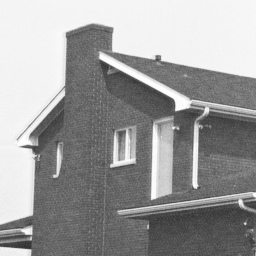

% TEST 0a

I = readim('house.tif');
I = double(I);
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

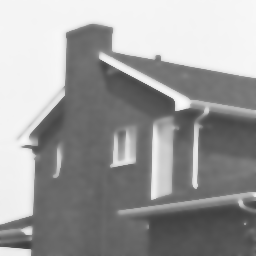

Ia = anisotropic(I, 0.15, 30.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

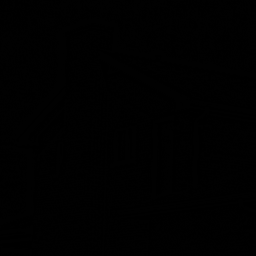

Imethodnoise = I - Ia;
dipshow(mat2im(Imethodnoise + 0.5))
f = gcf;
f.Name = 'Anisotropic method noise';
f.NumberTitle = 'off';

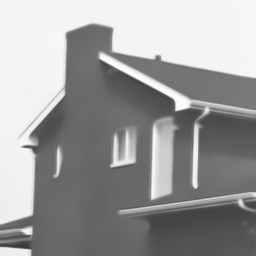

valueSigma = 0.045;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';

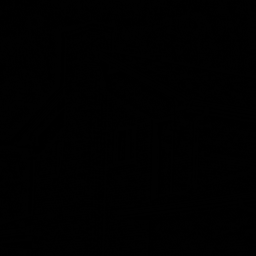

Imethodnoise = I - Inlm;
dipshow(mat2im(Imethodnoise + 0.5))
f = gcf;
f.Name = 'NLM method noise';
f.NumberTitle = 'off';

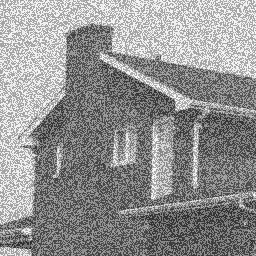

% TEST 1a

I = readim('house.tif');
I = double(I);
I = I + 0.5 * double(readim('anoise.tif'));
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

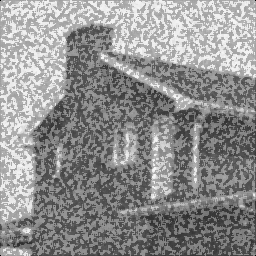

Im = medfilt2(I);
dipshow(mat2im(Im),'unit')
f = gcf;
f.Name = 'Median filtered image';
f.NumberTitle = 'off';

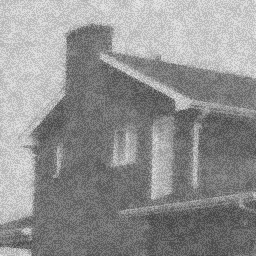

Ib = bilateral(I, 0.333, 5);
dipshow(mat2im(Ib),'unit')
f = gcf;
f.Name = 'Bilateral filtered image';
f.NumberTitle = 'off';

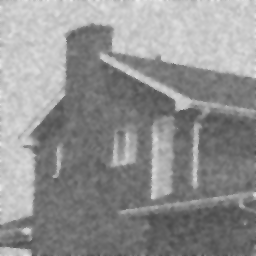

Ia = anisotropic(I, 0.15, 30.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

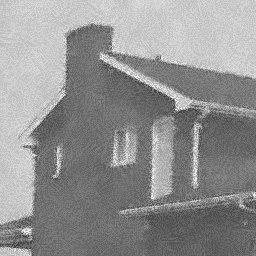

valueSigma = 0.045;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';

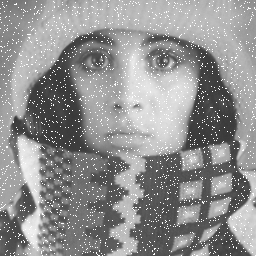

% TEST 1b

I = readim('trui.tif');
I = double(noise(I, 'saltpepper', 0.05));
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

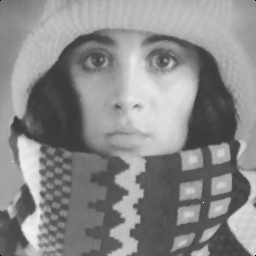

Im = medfilt2(I);
dipshow(mat2im(Im),'unit')
f = gcf;
f.Name = 'Median filtered image';
f.NumberTitle = 'off';

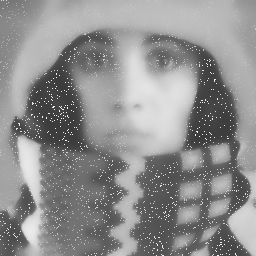

Ib = bilateral(I, 0.333, 5);
dipshow(mat2im(Ib),'unit')
f = gcf;
f.Name = 'Bilateral filtered image';
f.NumberTitle = 'off';

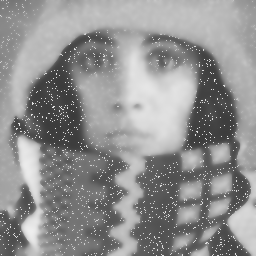

Ia = anisotropic(I, 0.15, 30.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

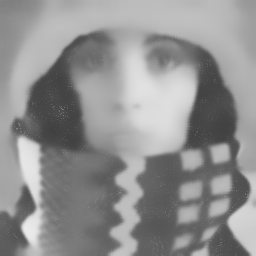

valueSigma = 0.075;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';

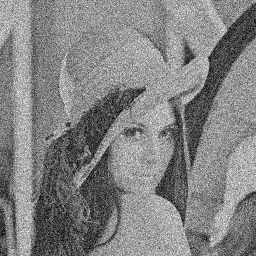

% TEST 1c

I = readim('lena.tif');
I = double(noise(I, 'gaussian', 30.0));
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

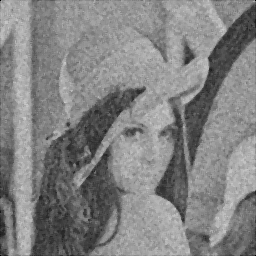

Im = medfilt2(I);
dipshow(mat2im(Im),'unit')
f = gcf;
f.Name = 'Median filtered image';
f.NumberTitle = 'off';

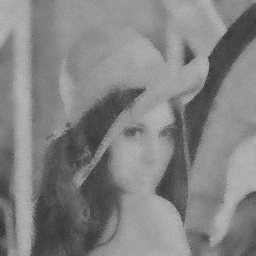

Ib = bilateral(I, 0.333, 5);
dipshow(mat2im(Ib),'unit')
f = gcf;
f.Name = 'Bilateral filtered image';
f.NumberTitle = 'off';

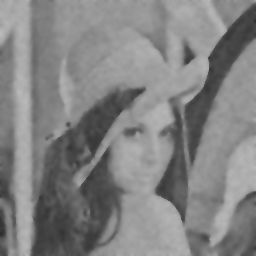

Ia = anisotropic(I, 0.15, 30.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

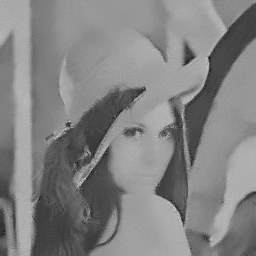

valueSigma = 0.035;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';

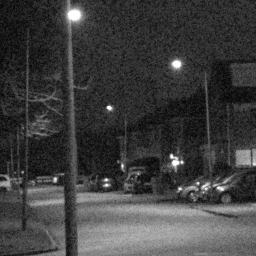

% TEST 2

I = readim('street.png');
I = double(I);
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

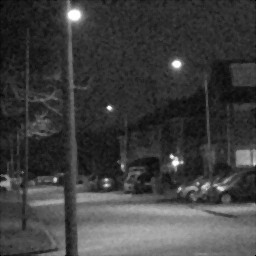

Im = medfilt2(I);
dipshow(mat2im(Im),'unit')
f = gcf;
f.Name = 'Median filtered image';
f.NumberTitle = 'off';

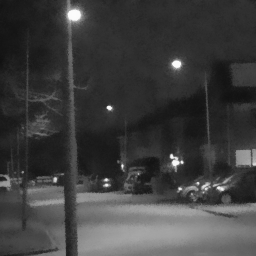

Ib = bilateral(I, 0.125, 5);
dipshow(mat2im(Ib),'unit')
f = gcf;
f.Name = 'Bilateral filtered image';
f.NumberTitle = 'off';

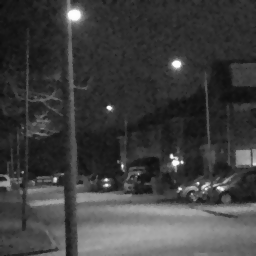

Ia = anisotropic(I, 0.08, 10.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

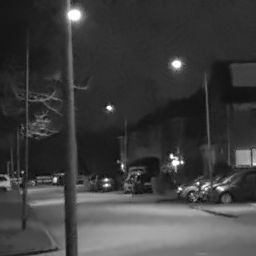

valueSigma = 0.015;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';

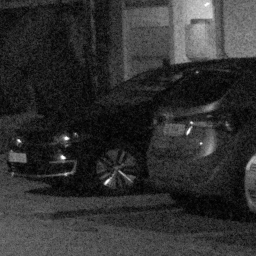

% TEST 3

I = readim('car.png');
I = double(I);
I = I ./ max(I, [], 'all');
dipshow(mat2im(I),'unit')
f = gcf;
f.Name = 'Original image';
f.NumberTitle = 'off';

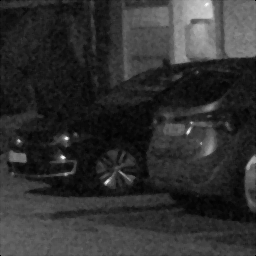

Im = medfilt2(I);
dipshow(mat2im(Im),'unit')
f = gcf;
f.Name = 'Median filtered image';
f.NumberTitle = 'off';

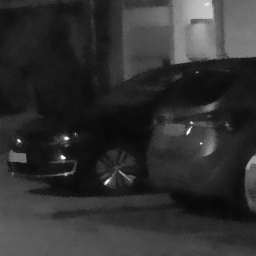

Ib = bilateral(I, 0.125, 5);
dipshow(mat2im(Ib),'unit')
f = gcf;
f.Name = 'Bilateral filtered image';
f.NumberTitle = 'off';

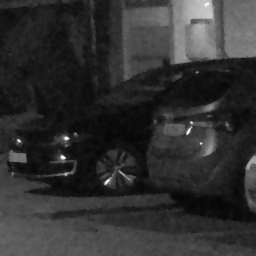

Ia = anisotropic(I, 0.08, 10.0 / 255.0, 200);
dipshow(mat2im(Ia),'unit')
f = gcf;
f.Name = 'Anisotropic filtered image';
f.NumberTitle = 'off';

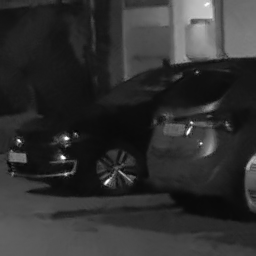

valueSigma = 0.015;
distSigma = 12;
searchRadius = 10;
tileRadius = 3;
Inlm = nlm(I, valueSigma, distSigma, tileRadius, searchRadius);

dipshow(mat2im(Inlm),'unit')
f = gcf;
f.Name = 'NLM Filtered image';
f.NumberTitle = 'off';